First I compute the covariance matrix of the STA. Each pixel (60 x 60 pixels for 3 chromatic channels == 10800 pixels) is a variable that is observed once per lag (in this example, 10 lags). 

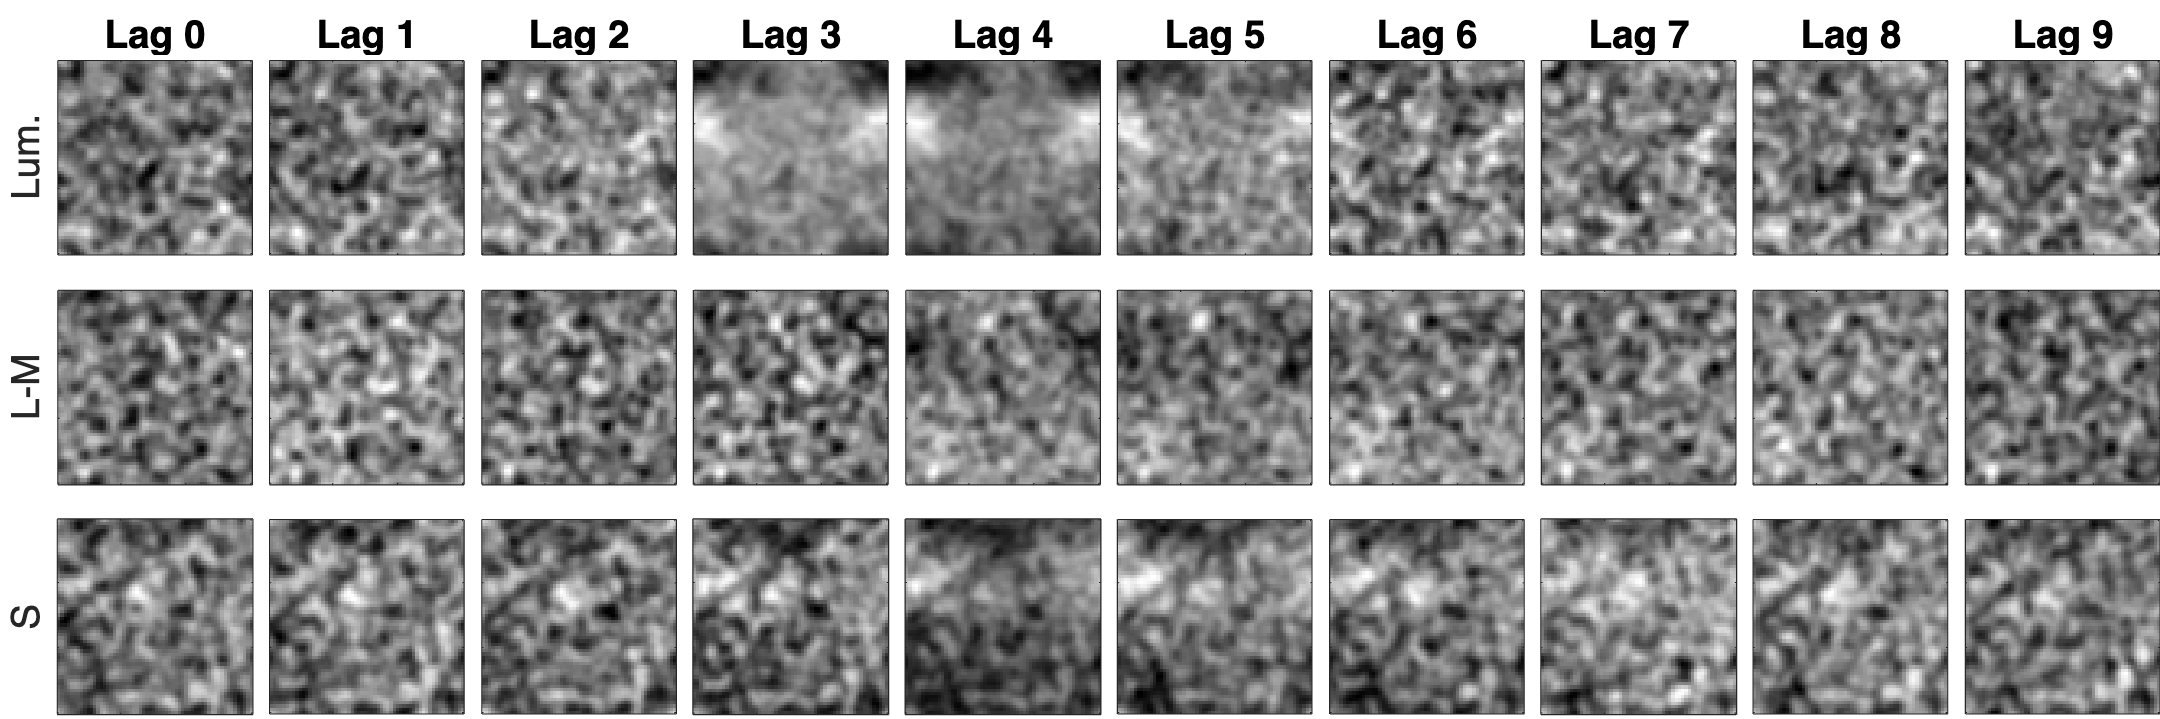

% Plotting params
fontSize = 16;
lineWidth = 2;

% Compute covariance matrix of STA

nLags = size(STA.DKL, 5);
nUnits = size(STA.DKL,1);
nx = size(STA.DKL,3);
ny = size(STA.DKL,2);
nchrom_chans = size(STA.DKL,4);

unit = 1;

thisSTA = squeeze(STA.DKL(unit,:,:,:,:));%
thisSTA = circshift(thisSTA, [30, 30]);


figure; tiledlayout(nchrom_chans, nLags, "TileSpacing","compact", "Padding","tight");

for i = 1:nchrom_chans
    for j = 1:nLags
        nexttile;
        %subplot(nchrom_chans, nLags, pp)
        imagesc(thisSTA(:,:,i,j)); colormap gray; axis image
        set(gca, 'FontSize', fontSize, 'XTickLabel', [], 'YTickLabel', [])

        if i == 1
            title(['Lag ' num2str(j-1)])

        end

        if j == 1
             ylabel(chrom_chan_labels{i})
        end
    end
end

set(gcf, 'position',  [0 0 1000 1000/3])

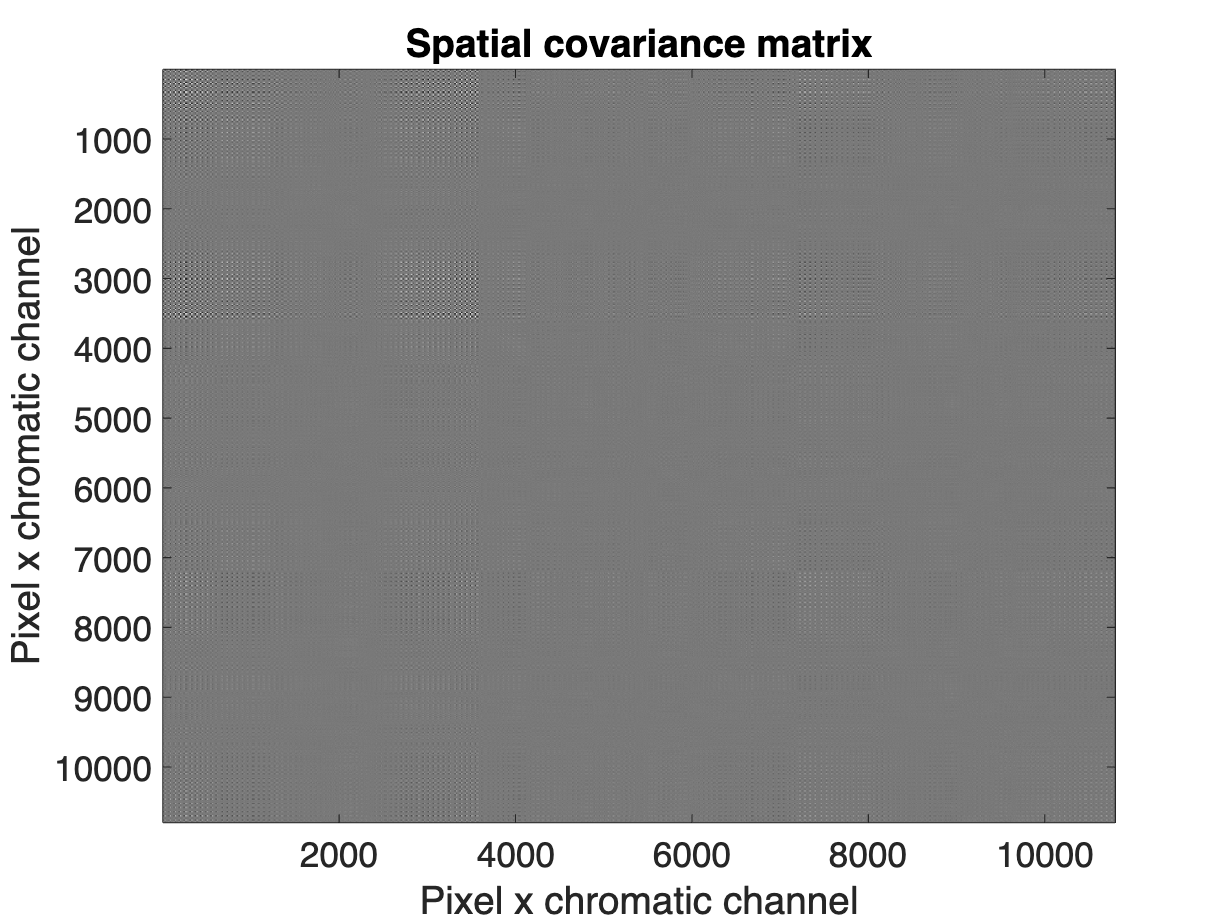


C = cov(transpose(reshape(thisSTA, [], nLags)));

C_spatial = cov(transpose(reshape(thisSTA, [], nLags)));
figure;
imagesc(C_spatial); colormap gray
title('Spatial covariance matrix', 'FontSize', 16)
xlabel('Pixel x chromatic channel')
ylabel('Pixel x chromatic channel')
set(gca, 'FontSize', fontSize)

C_temporal = cov(reshape(permute(thisSTA, [1 2 4 3]), [], nchrom_chans * nLags)); colormap gray

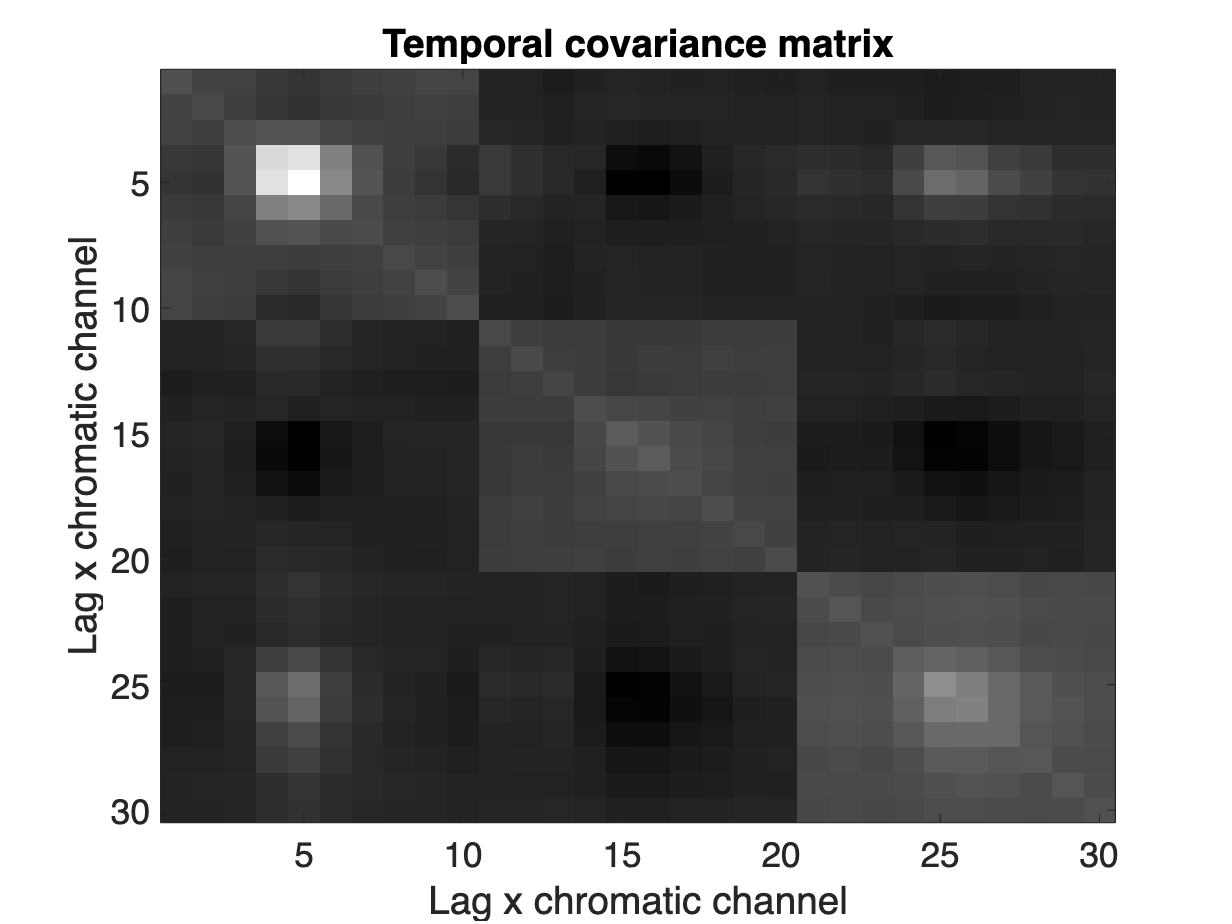


figure;
imagesc(C_temporal); colormap gray
title('Temporal covariance matrix', 'FontSize', fontSize)
xlabel('Lag x chromatic channel')
ylabel('Lag x chromatic channel')
set(gca, 'FontSize', fontSize)

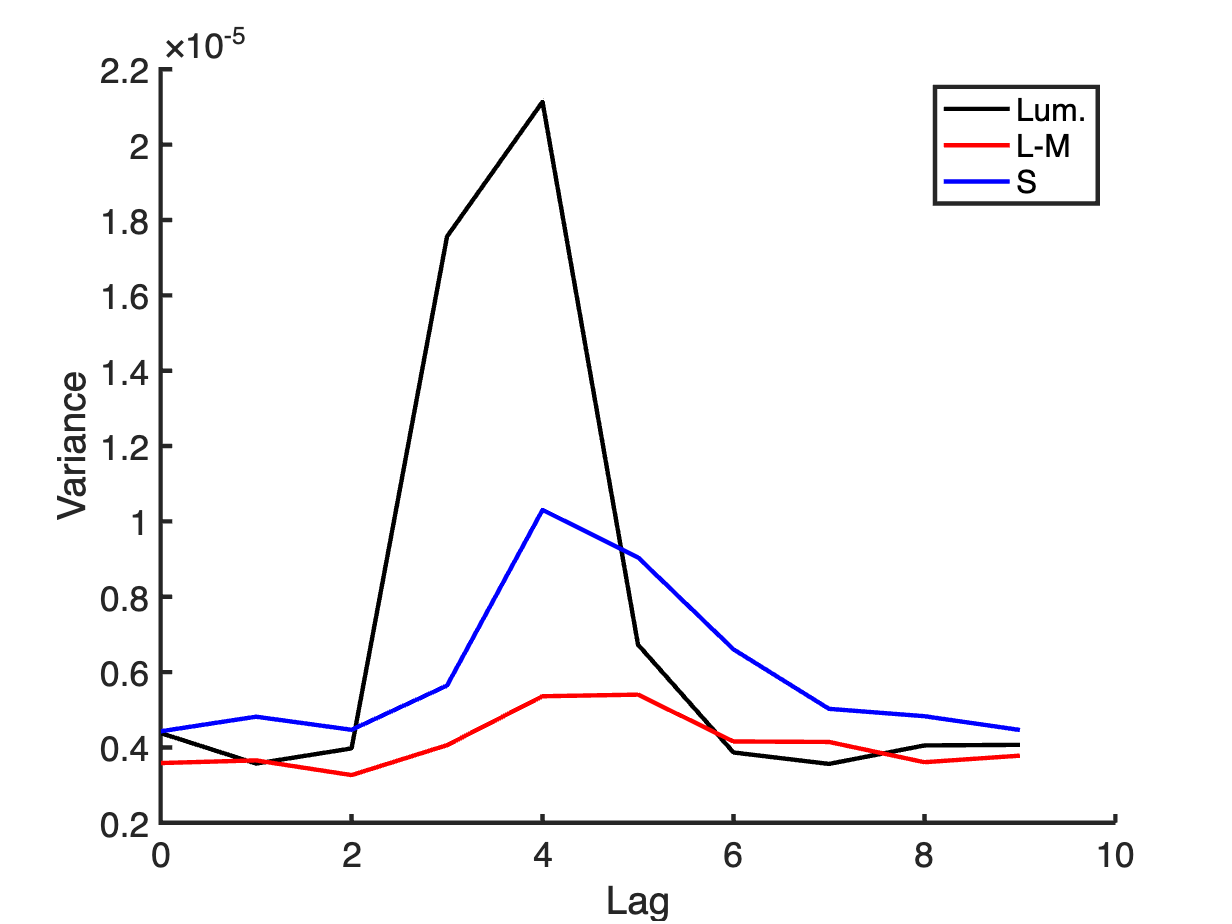



C_temporal_diag = diag(C_temporal);

colors = {'k', 'r', 'b'};
chrom_chan_labels = {'Lum.', 'L-M', 'S'};

figure; hold on
for i = 1:nchrom_chans
    plot(0:nLags-1, C_temporal_diag((nLags*(i-1) + 1): nLags*i ), colors{i}, 'linewidth',2, 'DisplayName', chrom_chan_labels{i}) 
end
legend show
xlabel('Lag')
ylabel('Variance')
set(gca, 'FontSize', fontSize, 'LineWidth', lineWidth)

%set(gca, 'FontSize')

Then I sum the absolute value of the covariance matrix across columns (or rows). I get a number for each pixel, which is bigger the more that pixel covaries with other pixels. I can set a threshold to mask out the "noise" in the STA (pixels who don't meet this threshold). In this case threshold is the 90th percentile of the sum of the absolute covariances (and thus changes appropriately with different STAs). 

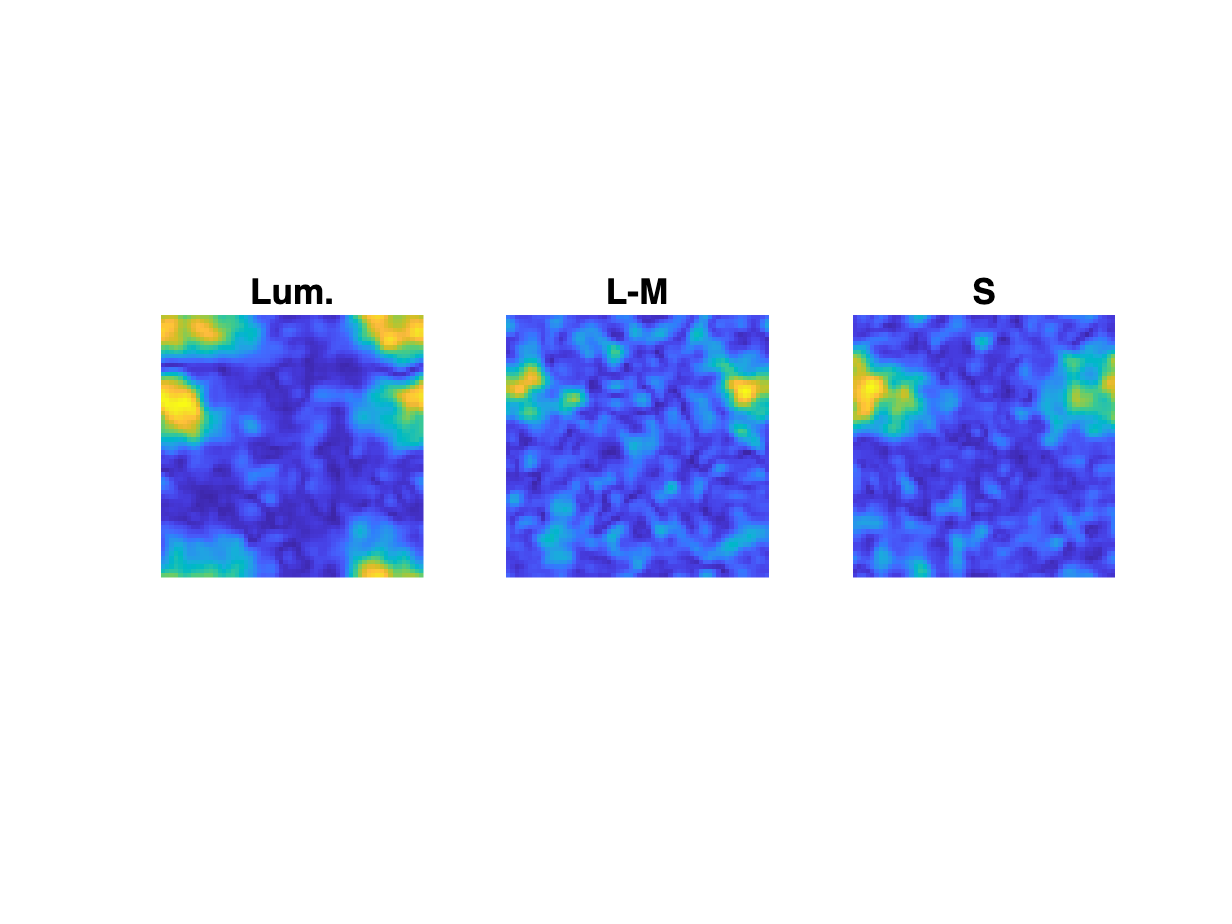

C_sum = sum(abs(C),2);

figure;
for i = 1:nchrom_chans
    subplot(1,nchrom_chans,i)
    idx = (i-1)*(nx*ny)+1:(nx*ny)*i;
    imagesc(reshape(C_sum(idx), ny, nx)); axis square off
    title(chrom_chan_labels{i}, 'FontSize', fontSize)
end

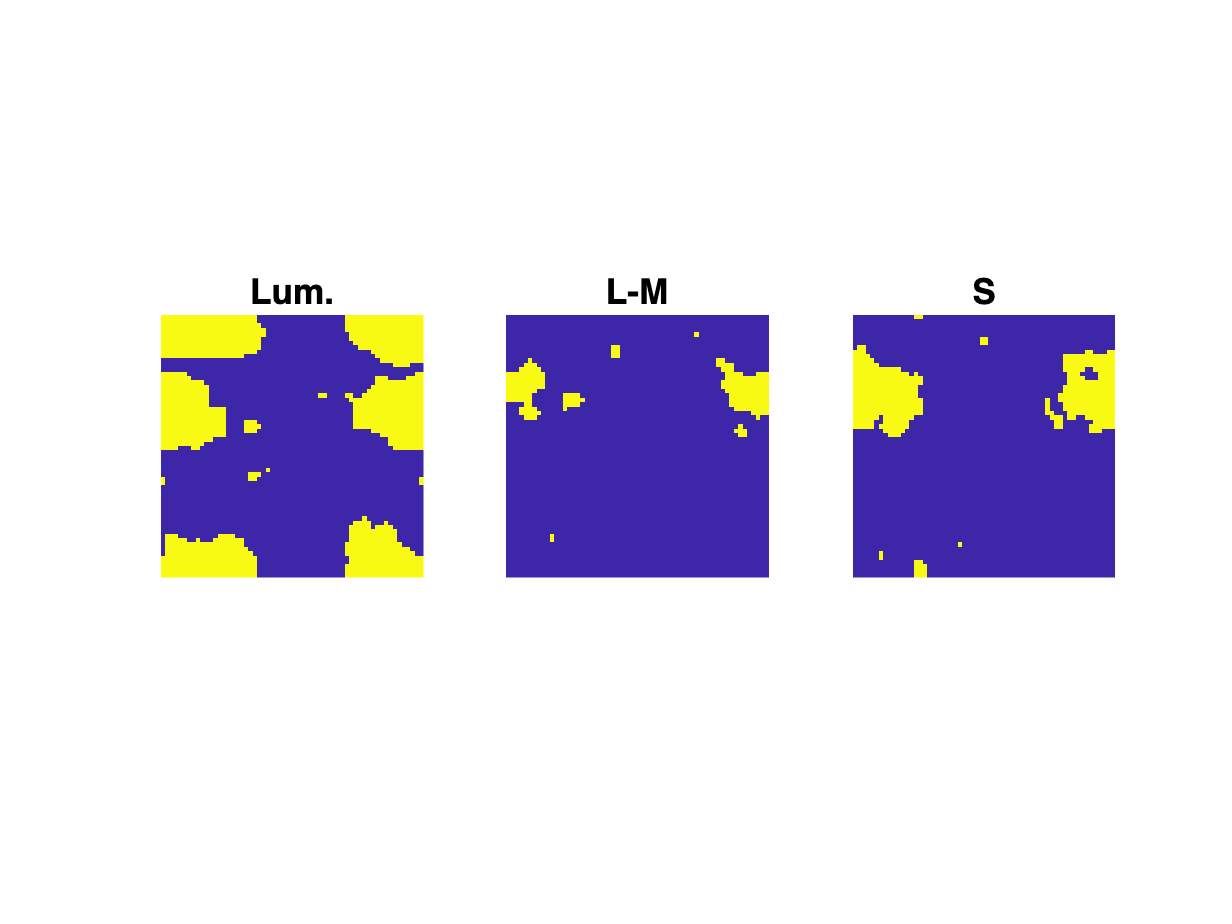


thresh =  3 * rms(C_sum(C_sum < prctile(C_sum, 50)));
mask = C_sum > thresh;
figure;
for i = 1:nchrom_chans
    subplot(1,nchrom_chans,i)
    idx = (i-1)*(nx*ny)+1:(nx*ny)*i;
    imagesc(reshape(mask(idx), ny, nx)); axis square off
    title(chrom_chan_labels{i}, 'FontSize', fontSize)

end

## Example STA at lag 4:

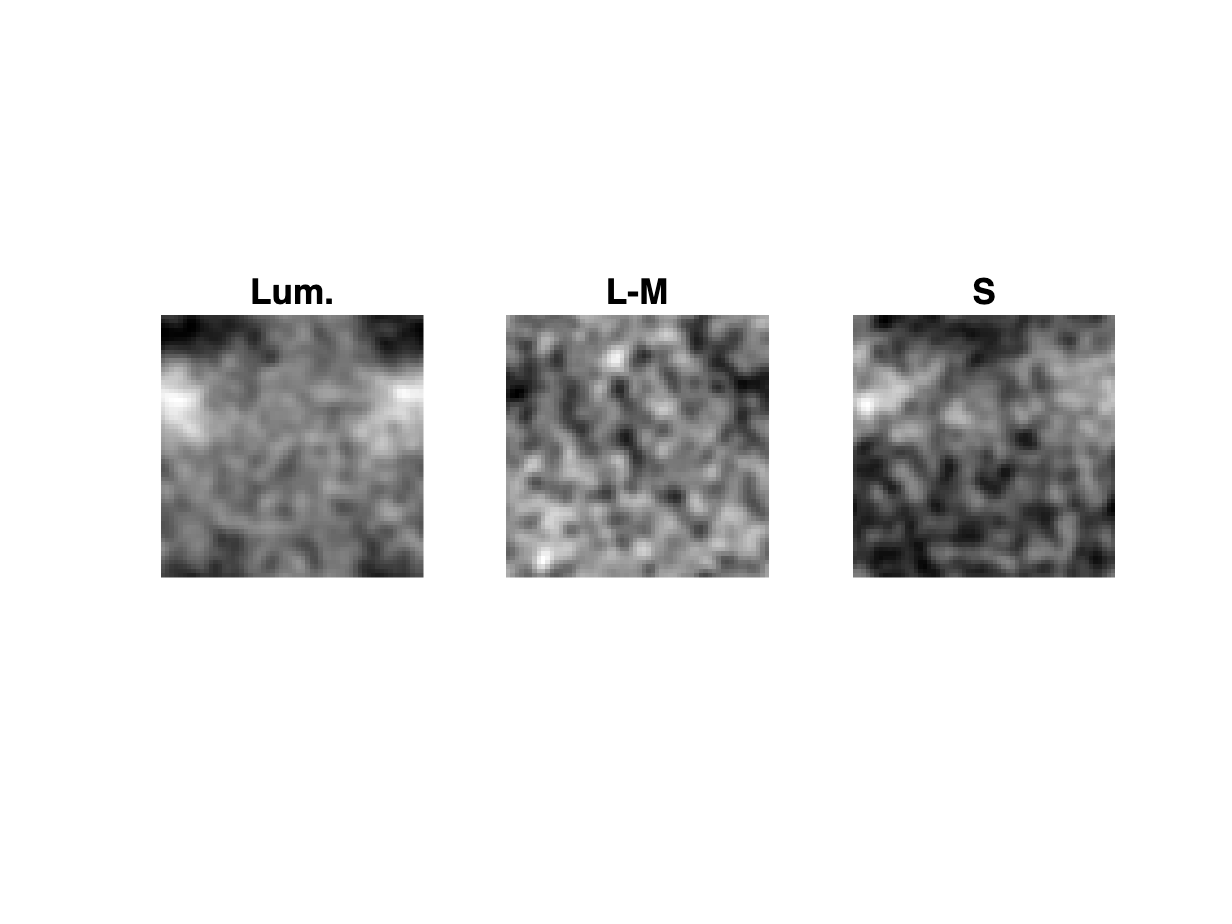

%mask = C_sum > thresh;
mask = reshape(mask, size(thisSTA,1), size(thisSTA,2), 3);

figure;

lag = 5;
for i = 1:nchrom_chans

    subplot(1,nchrom_chans,i)
    imagesc(thisSTA(:,:,i,lag)); axis square off
    title(chrom_chan_labels{i}, 'FontSize', fontSize)
    colormap gray

end

## Same STA with "noise" / "insignificant" pixels masked:

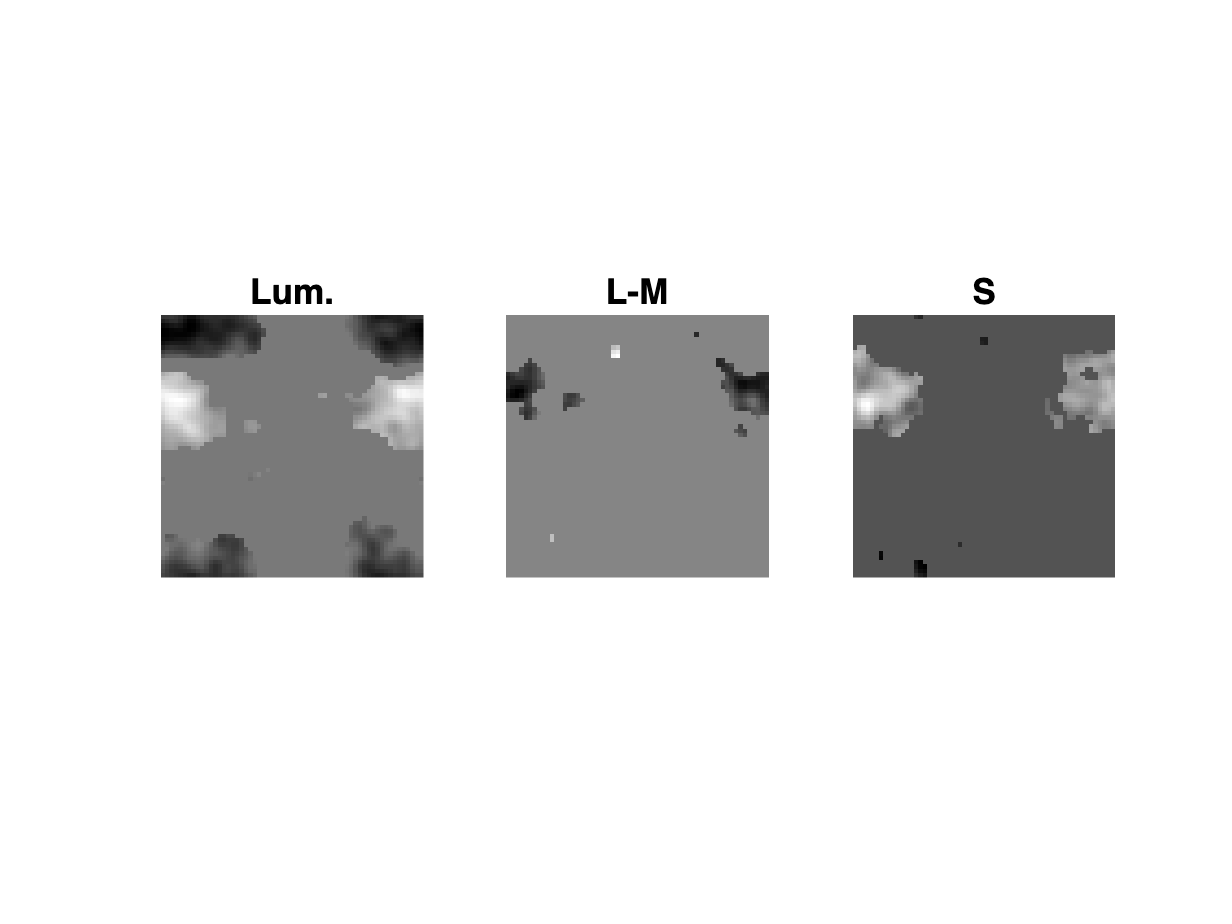


figure;

for i = 1:nchrom_chans

    subplot(1,nchrom_chans,i)
    imagesc(thisSTA(:,:,i,lag) .* mask(:,:,i)); axis square off
    title(chrom_chans{i}, 'FontSize', 16)
    colormap gray

end

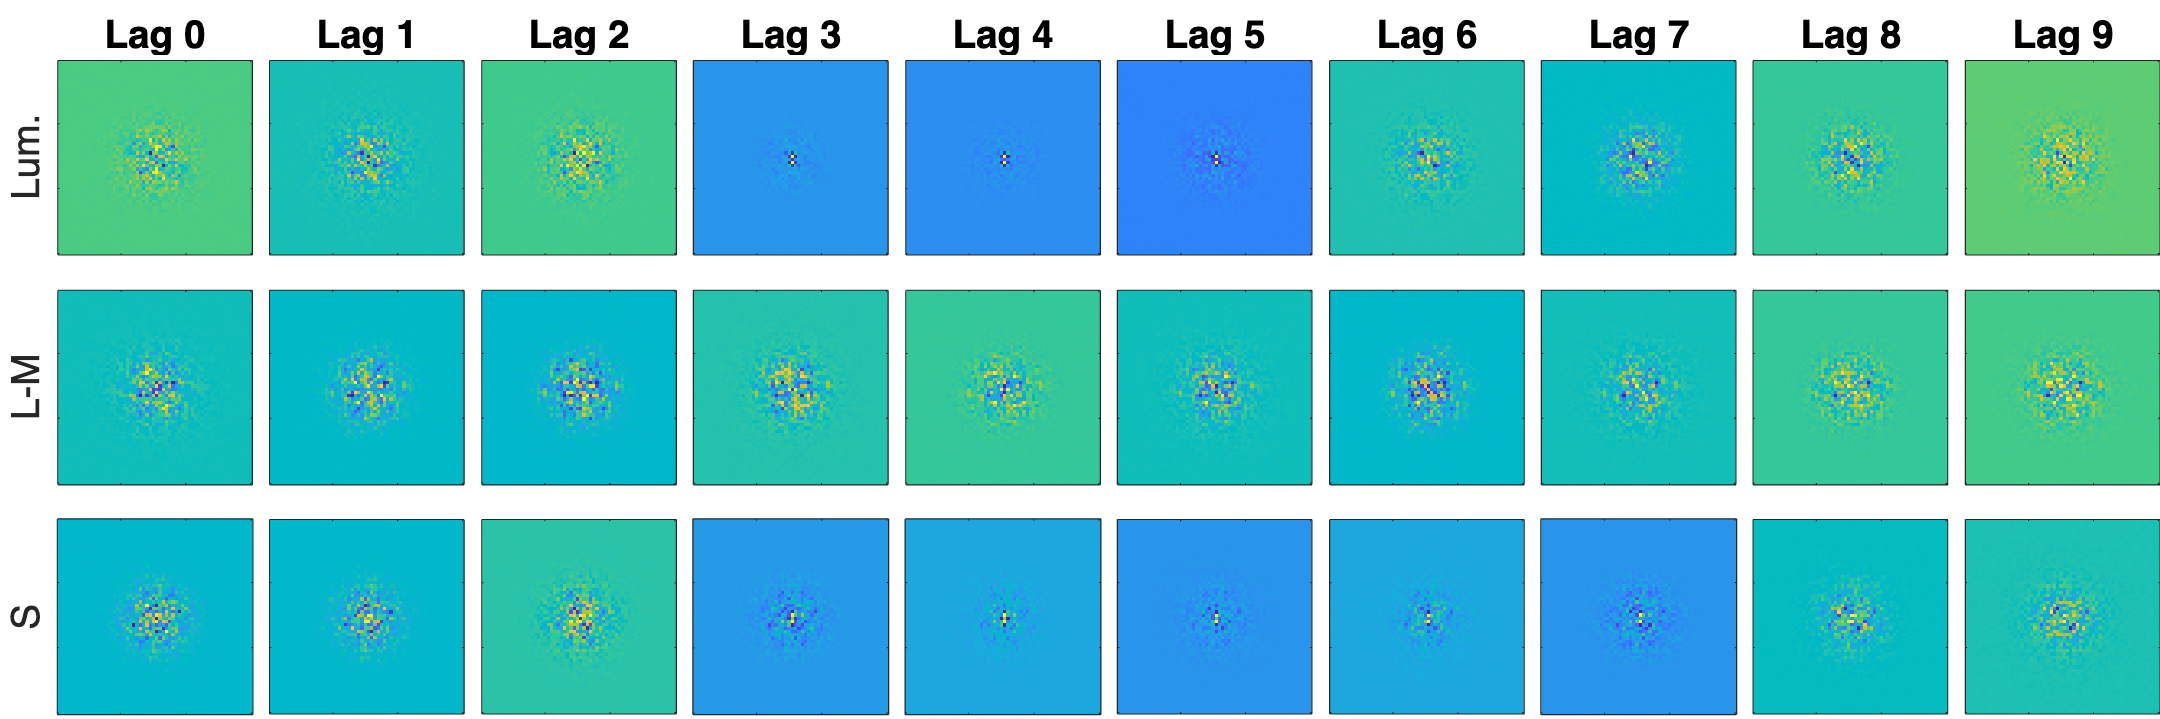

F = fftshift(fftshift(fft2(permute(STA.DKL, [2 3 1 4 5])), 1), 2);
F = permute(F, [3 1 2 4 5]);

figure; tiledlayout(nchrom_chans, nLags, "TileSpacing","compact", "Padding","tight");

for i = 1:nchrom_chans
    for j = 1:nLags
        nexttile;
        %subplot(nchrom_chans, nLags, pp)
        imagesc(squeeze(real(F(unit,:,:,i,j)))); axis image
        set(gca, 'FontSize', fontSize, 'XTickLabel', [], 'YTickLabel', [])

        if i == 1
            title(['Lag ' num2str(j-1)])

        end

        if j == 1
             ylabel(chrom_chan_labels{i})
        end
    end
end

set(gcf, 'position',  [0 0 1000 1000/3])

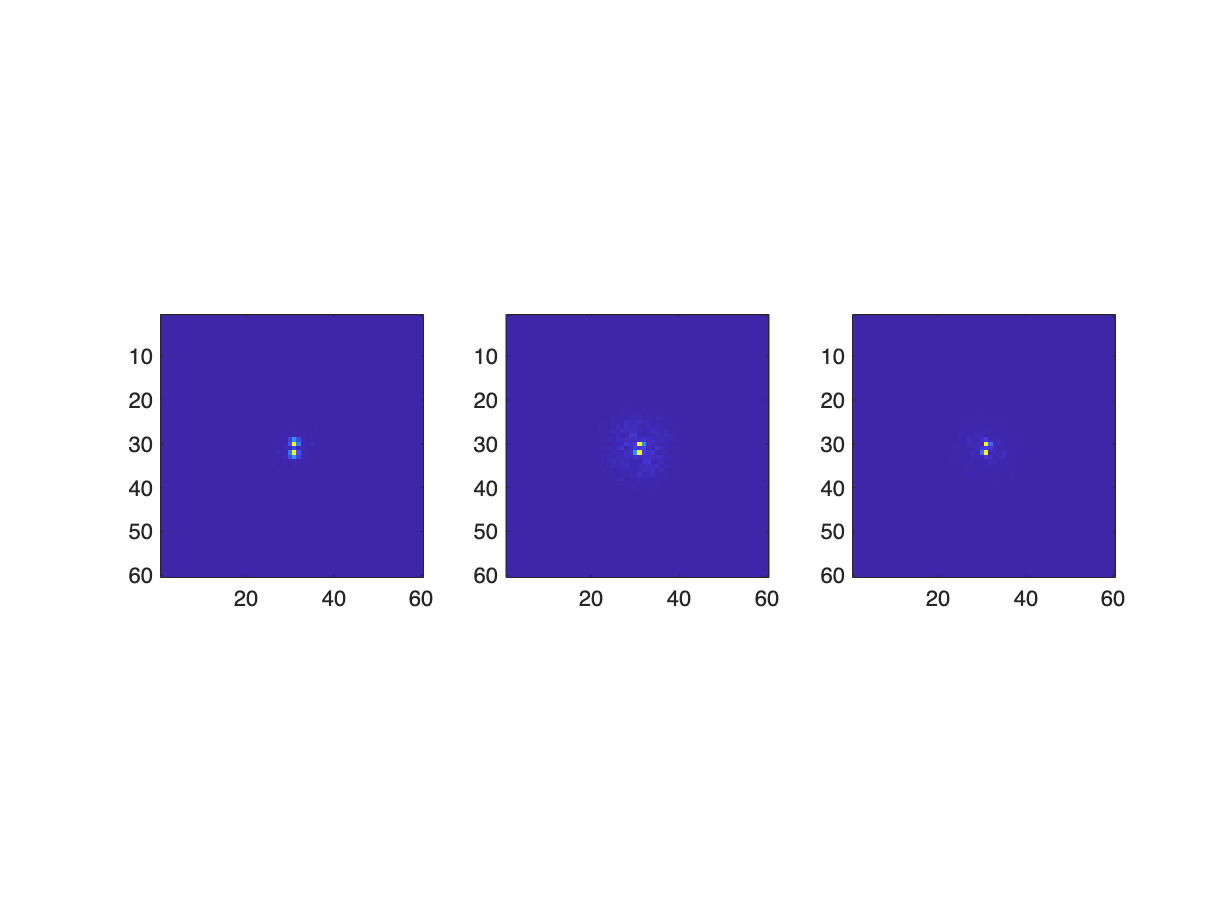

figure;
for i = 1:nchrom_chans
V = squeeze(var(abs(F(unit,:,:,i,:)),[], 5));
subplot(1,3,i)
imagesc(V); axis square
end

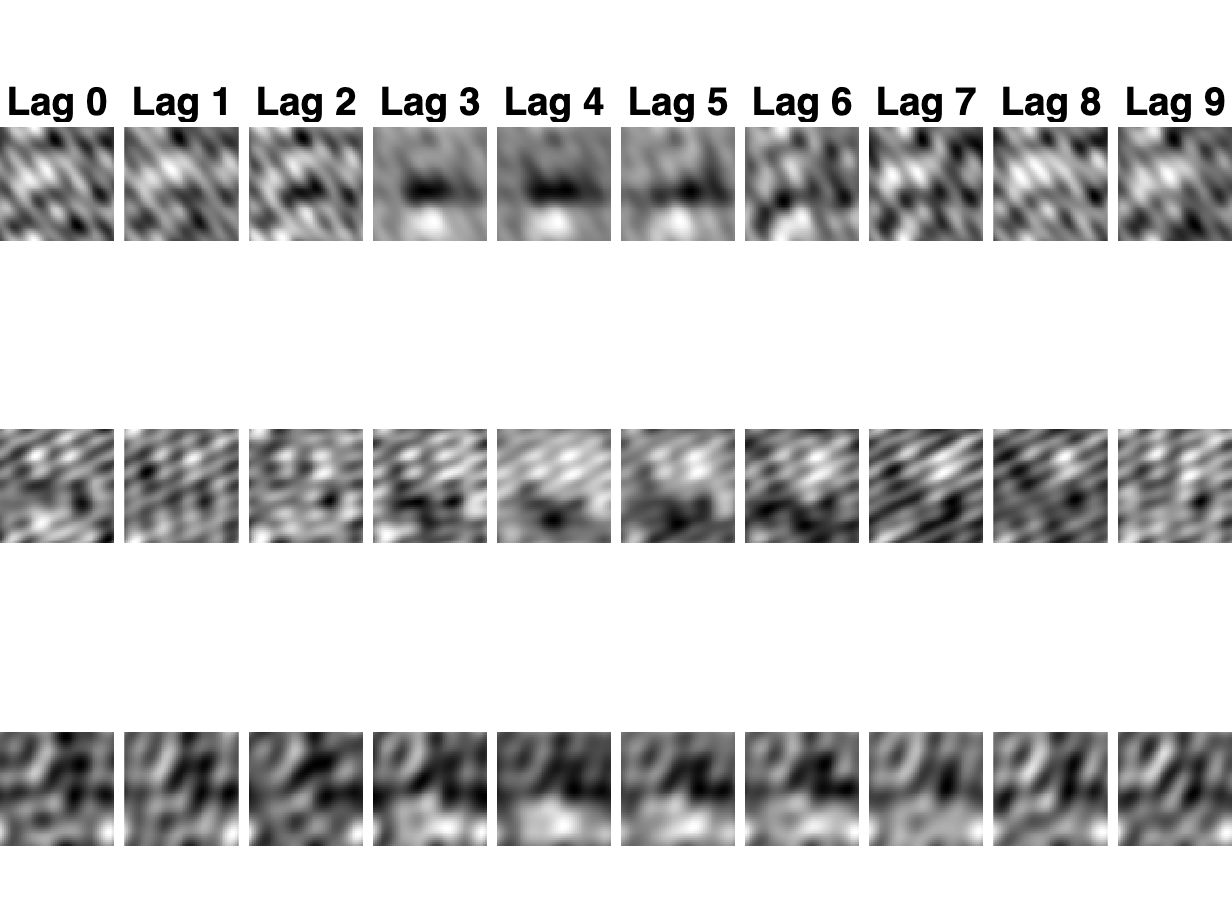


figure; tiledlayout(nchrom_chans, nLags, "TileSpacing","compact", "Padding","tight");

for i = 1:nchrom_chans
    for j = 1:nLags
        nexttile;
        %subplot(nchrom_chans, nLags, pp)
        V = squeeze(var(abs(F(unit,:,:,i,:)),[], 5));
        H = V > prctile(V(:), 99);

        I_filtered_FT = fftshift(fftshift(H).*squeeze((fftshift(F(unit,:,:,i,j)))));

        I_filtered = real(ifft2(fftshift(I_filtered_FT)));
        imagesc(I_filtered); axis image off; colormap gray
        set(gca, 'FontSize', fontSize, 'XTickLabel', [], 'YTickLabel', [])

        if i == 1
            title(['Lag ' num2str(j-1)])

        end

        if j == 1
             ylabel(chrom_chan_labels{i})
        end
    end
end

% 
% 
% I_filtered_FT = fftshift(fftshift(H).*squeeze((fftshift(F(unit,:,:,1,lag)))));
% 
% I_filtered = real(ifft2(fftshift(I_filtered_FT)));
% 
% %I_filtered = circshift(I_filtered, [30 30]);
% figure, imagesc(I_filtered); colormap gray


% 
% 
% 
% figure, imagesc(squeeze(STA.DKL(unit,:,:,1,lag))); colormap gray